% Fixed parameters
T_total = 200000;                  
longDRX_cycle = 512;              
inactivity_timer = 100;             
on_duration = 10;                  
packet_reception_time = 10;        
minTimeGap_fixed = 0.5;            

% Tested parameters
ps_Offset_values = 1:3:15; % 1:0.125:15
packet_frequencies = [1000, 2000, 5000, 10000]; 

% Preallocate results
energy_gains = zeros(length(packet_frequencies), length(ps_Offset_values));
mean_delays = zeros(length(packet_frequencies), length(ps_Offset_values));

% Simulation loop
for freq_idx = 1:length(packet_frequencies)
    for ps_idx = 1:length(ps_Offset_values)
        [energy_gains(freq_idx, ps_idx), mean_delays(freq_idx, ps_idx)] = ...
            wus_drx_script(...
                T_total, longDRX_cycle, inactivity_timer, on_duration, ...
                packet_frequencies(freq_idx), packet_reception_time, ...
                ps_Offset_values(ps_idx), minTimeGap_fixed);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 200000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 10 ms
Packet frequency: 1000 ms
Packet reception time: 10 ms
ps-Offset time: 1 ms
minTimeGap time: 5.000000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 411 ms (Energy: 650.3 mJ)
[Energy update] Total: 10650.3 mJ | Saved: 0.1%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #2)
[Energy after WUS] Total: 10700.3 mJ | Saved: 0.1%
DEEP_SLEEP: 5.115000e+02 ms (Energy: 750.8 mJ)
[Energy update] Total: 11451.1 mJ | Saved: 0.1%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 1
[Packet #2 arrived during SLEEP at last cycle at 1000 ms]
-> State change: WAKE_UP SIGNAL -> ON DURATION (Cycle #3)
[Energy after WUS] Total: 11501.1 mJ | Saved: 0.1%
LIGHT_SLEEP

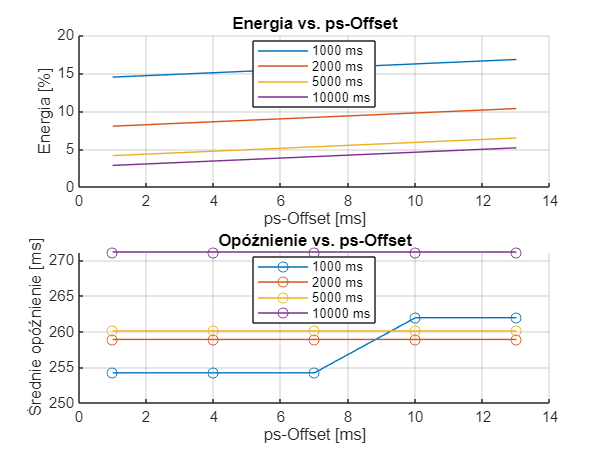


% Utwórz nowe okno graficzne
figure;

% Wykres energii
subplot(2, 1, 1);
hold on;
colors = lines(length(packet_frequencies));
for freq_idx = 1:length(packet_frequencies)
    plot(ps_Offset_values, energy_gains(freq_idx, :), ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('%d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Energia vs. ps-Offset');
xlabel('ps-Offset [ms]');
ylabel('Energia [%]');
legend('Location', 'best', 'FontSize', 8);
grid on;

% Wykres opóźnień
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequencies)
    plot(ps_Offset_values, mean_delays(freq_idx, :), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('%d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Opóźnienie vs. ps-Offset');
xlabel('ps-Offset [ms]');
ylabel('Średnie opóźnienie [ms]');
legend('Location', 'best', 'FontSize', 8);
grid on;

% Dostosuj układ
set(gcf, 'Position', [100 100 800 600]);

% Fixed parameters
T_total = 500000;                  
longDRX_cycle = 512;              
inactivity_timer = 100;             
on_duration = 50;                  
packet_reception_time = 10; 
ps_Offset_fixed = 7.5;               % Fixed ps-Offset (ms)

% Tested parameters
minTimeGap_values = [0.25, 0.5, 1, 3]; % minTimeGap range (ms)          
packet_frequencies = [1000, 2000, 5000, 10000]; 

% Preallocate results
energy_gains = zeros(length(packet_frequencies), length(minTimeGap_values));
mean_delays = zeros(length(packet_frequencies), length(minTimeGap_values));

% Simulation loop
for freq_idx = 1:length(packet_frequencies)
    for ps_idx = 1:length(minTimeGap_values)
        [energy_gains(freq_idx, ps_idx), mean_delays(freq_idx, ps_idx)] = ...
            wus_drx_script(...
                T_total, longDRX_cycle, inactivity_timer, on_duration, ...
                packet_frequencies(freq_idx), packet_reception_time, ...
                ps_Offset_fixed, minTimeGap_values(ps_idx));
    end
end


=== Starting DRX Simulation ===
Total simulation time: 500000 ms
Long DRX cycle: 512 ms
Inactivity timer: 100 ms
On duration: 50 ms
Packet frequency: 1000 ms
Packet reception time: 10 ms
ps-Offset time: 7.500000e+00 ms
minTimeGap time: 2.500000e-01 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 100 ms (Energy: 10000.0 mJ)
! STATE ON time counter: 100)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 4.045000e+02 ms (Energy: 643.8 mJ)
[Energy update] Total: 10643.8 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 0 - no packet arrived 
-> State change: WAKE_UP SIGNAL -> SLEEP (Cycle #2)
[Energy after WUS] Total: 11368.8 mJ | Saved: 0.0%
DEEP_SLEEP: 5.047500e+02 ms (Energy: 744.1 mJ)
[Energy update] Total: 12112.9 mJ | Saved: 0.0%
-> State change: SLEEP -> wus_signal
WAKE UP SIGNAL : 1
[Packet #2 arrived during SLEEP at last cycle at 1000 ms]
-> State change: WAKE_UP SIGNAL -> ON DURATION (Cycle #3)
[Energy after WUS] Total: 12837.9 mJ | Sav

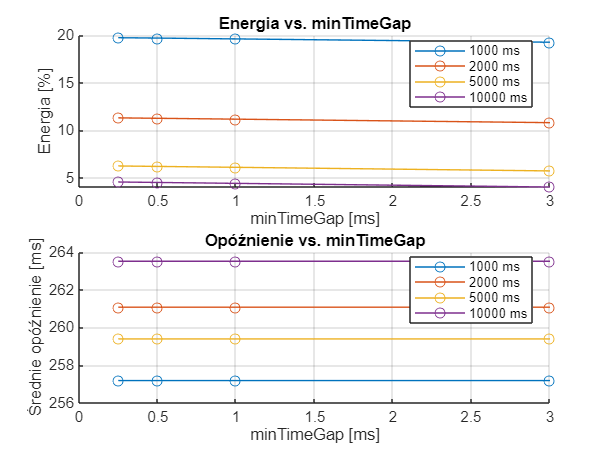



% Utwórz nowe okno graficzne
figure;

% Wykres energii
subplot(2, 1, 1);
hold on;
colors = lines(length(packet_frequencies));
for freq_idx = 1:length(packet_frequencies)
    plot(minTimeGap_values, energy_gains(freq_idx, :), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('%d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Energia vs. minTimeGap');
xlabel('minTimeGap [ms]');
ylabel('Energia [%]');
legend('Location', 'best', 'FontSize', 8);
grid on;

% Wykres opóźnień z dokładniejszym formatowaniem
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequencies)
    plot(minTimeGap_values, mean_delays(freq_idx, :), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('%d ms', packet_frequencies(freq_idx)));
end
hold off;

title('Opóźnienie vs. minTimeGap');
xlabel('minTimeGap [ms]');
ylabel('Średnie opóźnienie [ms]');
legend('Location', 'best', 'FontSize', 8);
grid on;